# Plots

clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Qband spectrum with lines at g = 2.003 and g = 2.0065

gm_07_20230622_fit

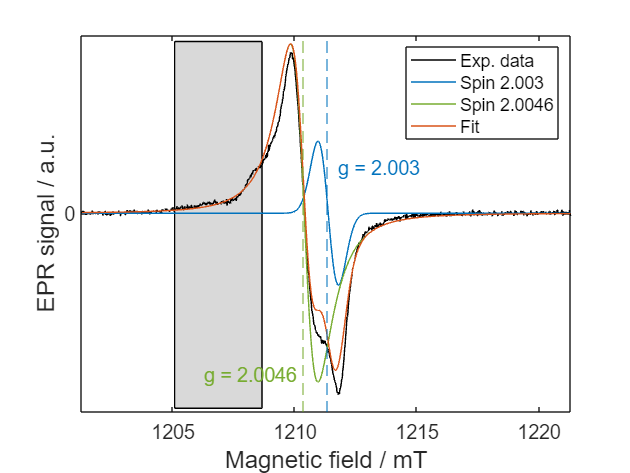

load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
load('data/processed/gm20230622_sample4_Qband_mwpw_18dB_fit.mat');
load("plotColors.mat");
ICW = 5;
x = cw(ICW).x;
y = -real(cw(ICW).y2);

figure()
plot(x, y, 'Color', plotColors(1), 'DisplayName', 'Exp. data')
hold on
plot(x, Fit.fit, 'Color', plotColors(2), 'DisplayName', 'Fit')
plot(x, Fit.yFit0, 'Color',  plotColors(3),  'DisplayName', 'Spin 2.0046')
plot(x, Fit.yFit1, 'Color',  plotColors(4), 'DisplayName', 'Spin 2.003')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.0046), '--', 'Color', plotColors(3), 'HandleVisibility', 'off')
xline(mhz2mt(cw(ICW).Params.MWFQ*1e-6, 2.003), '--', 'Color', plotColors(4), 'HandleVisibility', 'off')
rectangle('position', [x(195) -25 (x(378) - x(195)) 47], 'FaceColor', [.85 .85 .85])

Label = "g = 2.0046";
text(0.25, 0.1, Label, 'Units', 'normalized', ...
    'FontSize', 13, 'Color', plotColors(3));
Label = "g = 2.003";
text(0.525, 0.65, Label, 'Units', 'normalized', ...
'FontSize', 13, 'Color', plotColors(4));

chH = get(gca, "Children");
set(gca,'Children',[chH(6);chH(5);chH(4);chH(7);chH(3);chH(2);chH(1)])

ylim(setAxLim(y, 0.05))
xlim(setAxLim(x, 0))
yticks(0)
legend()
labelAxesFig(gca, "Magnetic field / mT", "EPR signal / a.u.")

% exportFig(gcf, 'images', 'sijia-fig-00001', '.svg')

## X-band and Q-band plotted on a g-value axis

X-band: gm_09_20230720_dataPreparation,

Q-band: gm_06_20230622_dataPreparation

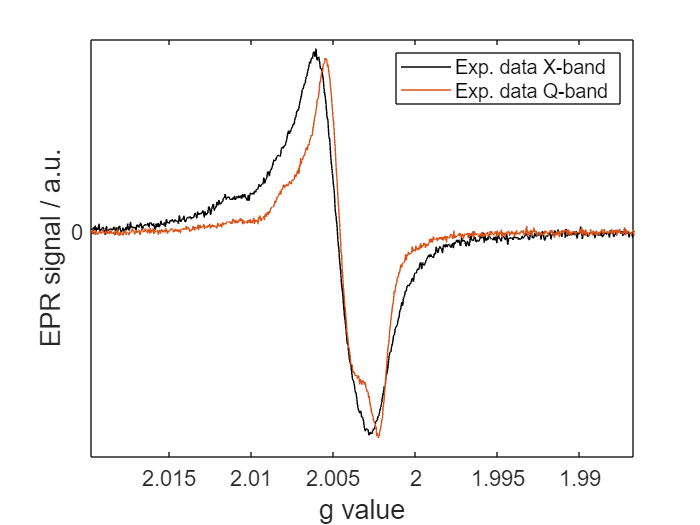

load('data/processed/gm20230720_sample4.mat');
cwX = cw;
load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
cwQ = cw(5);
load("plotColors.mat");

gaxX = planck*cwX.Params.MWFQ/bmagn./(cwX.x/1000);
gaxQ = planck*cwQ.Params.MWFQ/bmagn./(cwQ.x/1000);
% figure()
% tiledlayout('flow', 'TileSpacing', 'tight', 'Padding', 'tight')
% nexttile
% plot(cwX.x, cwX.y)
% xlim(setAxLim(cwX.x, 0))
% ylim(setAxLim(cwX.y, 0.05))
% nexttile
% plot(gaxX, cwX.y)
% xlim(setAxLim(gaxX, 0))
% ylim(setAxLim(cwX.y, 0.05))
% set(gca, 'Xdir', 'reverse')
% nexttile
% plot(cwQ.x, cwQ.y)
% xlim(setAxLim(cwQ.x, 0))
% ylim(setAxLim(cwQ.y, 0.05))
% nexttile
% plot(gaxQ, cwQ.y)
% xlim(setAxLim(gaxQ, 0))
% ylim(setAxLim(cwQ.y, 0.05))
% set(gca, 'Xdir', 'reverse')
figure()

plot(gaxX, rescaledata(cwX.y, cwQ.y, 'lsq'), 'Color', plotColors(1), 'DisplayName', 'Exp. data X-band')
hold on
plot(gaxQ, cwQ.y, 'Color', plotColors(2), 'DisplayName', 'Exp. data Q-band')

set(gca, 'Xdir', 'reverse')
ylim(setAxLim(cwQ.y, 0.05))
xlim(setAxLim(gaxQ, 0))
yticks(0)
legend()
labelAxesFig(gca, "g value", "EPR signal / a.u.")

% exportFig(gcf, 'images', 'sijia-fig-00002', '.svg')

# Comparison between X-band spectra of sample 1b in an X-band tube and sample 4 in an Q-band tube

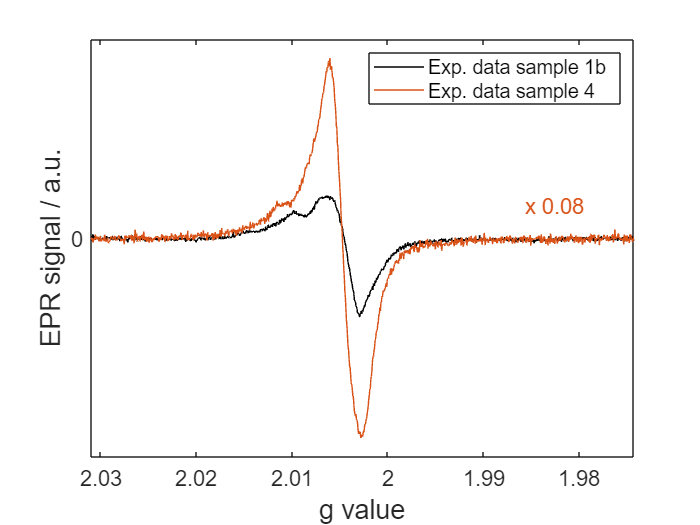

load('data/processed/gm20230720_sample4.mat');
cw4 = cw;
load('data/processed/gm20230804_sample1b.mat');
cw1b = cw;
load("plotColors.mat");

gax4 = planck*cw4.Params.MWFQ/bmagn./(cw4.x/1000);
gax1b = planck*cw1b.Params.MWFQ/bmagn./(cw1b.x/1000);

figure()
plot(gax1b, cw1b.y, 'Color', plotColors(1), 'DisplayName', 'Exp. data sample 1b')
hold on
plot(gax4, cw4.y, 'Color', plotColors(2), 'DisplayName', 'Exp. data sample 4')

set(gca, 'Xdir', 'reverse')
ylim(setAxLim(cw4.y, 0.05))
xlim(setAxLim(gax4, 0))

% Ratio between Q-band and X-band tube volume. Assume same height (max
% sample space of the SHQ resonator is 1cm, therefore it is a resonable
% assumption):
% (1mm)^2/(3.5mm)^2 = 0.0816.
Label = "x 0.08"; 
text(0.8, 0.6, Label, 'Units', 'normalized', ...
    'FontSize', 13, 'Color', plotColors(2));

yticks(0)
legend()
labelAxesFig(gca, "g value", "EPR signal / a.u.")

exportFig(gcf, 'reports/figures', 'sijia-fig-00003', '.svg')

Unrecognized function or variable 'exportFig'.

# Degradation of sample from SCOF005 to SCOF008 after 1 day of air exposure

X-band data

load("plotColors.mat");
figure()
tL = tiledlayout('flow', 'TileSpacing', 'none', 'Padding', 'compact');

data0 = load('data/processed/gm-e1-00034.mat');
data1 = load('data/processed/gm-e1-00038.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);
gax1 = planck.*data1.data.Params.MWFQ./bmagn./(data1.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))
hold on
plot(gax1, data1.data.y, 'Color', plotColors(2))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data0.data.y, 0.05))
yticks([])
xticks([])

data0 = load('data/processed/gm-e1-00035.mat');
data1 = load('data/processed/gm-e1-00039.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);
gax1 = planck.*data1.data.Params.MWFQ./bmagn./(data1.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))
hold on
plot(gax1, data1.data.y, 'Color', plotColors(2))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data0.data.y, 0.05))
yticks([])
xticks([])

data0 = load('data/processed/gm-e1-00036.mat');
data1 = load('data/processed/gm-e1-00040.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);
gax1 = planck.*data1.data.Params.MWFQ./bmagn./(data1.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))
hold on
plot(gax1, data1.data.y, 'Color', plotColors(2))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data1.data.y, 0.05))
yticks([])

data0 = load('data/processed/gm-e1-00037.mat');

gax0 = planck.*data0.data.Params.MWFQ./bmagn./(data0.data.x./1000);

nexttile
plot(gax0, data0.data.y, 'Color', plotColors(1))

set(gca, 'Xdir', 'reverse')
xlim([1.98 2.03])
ylim(setAxLim(data0.data.y, 0.05))
yticks([])

lgd = legendfirsttile(tL, {'8th Aug.', '9th Aug.'});
labelAxesFig(tL, "g value", "EPR signal / a.u.")
% exportFig(gcf, 'reports/figures', 'sijia-fig-00004', '.svg')

# Q-band SCOF006

clearvars
load("plotColors.mat");

figure()
iData = 1;
for isys = [44, 50]
    pathLoad = strcat("data/processed/gm-e1-000", string(isys), ".mat");
    dataArray(iData) = load(pathLoad);

    gax(iData, :) = planck.*dataArray(iData).data.Params.MWFQ./bmagn./(dataArray(iData).data.x./1000);
    
    yy(iData, :) = dataArray(iData).data.y/max(dataArray(iData).data.y);
    if iData == 1
        for ii = 1:2
            y_{iData}.y(ii, :) = cumtrapz(dataArray(iData).data.Fit.yFit(ii, :));
            y_{iData}.y(ii, :) = y_{iData}.y(ii, :);
        end   
    elseif iData == 2
        gtemp = planck.*dataArray(iData).data.Params.MWFQ./bmagn./((dataArray(iData).data.DataPrep.xRaw + 2.9)./10000);

        for ii = 1:3
            y_{iData}.y(ii, :) = dataArray(iData).data.Fit.yFit(ii, :);
            y_{iData}.y(ii, :) = y_{iData}.y(ii, :);
        end   
    end

    if iData > 1
        plot(gax(iData, :) - 0.003, yy(iData, :), "DisplayName", "Pulse corrected", "Color", plotColors(2))
        hold on
        plot(gtemp, yy(iData, :), "DisplayName", "Pulse raw", "Color", plotColors(3))
        % for ii = 1:3
        %     plot(gax(iData, :) - 0.003, y_{iData}.y(ii, :)/12e5, "DisplayName", "pulse")
        % end
    else
        plot(gax(iData, :), yy, "DisplayName", "cw", "Color", plotColors(end))
        hold on
        plot(gax(iData, :), cumtrapz(yy)/max(cumtrapz(yy)), "DisplayName", "Integ. cw", "Color", plotColors(1))
        % for ii = 1:2
        %     plot(gax(iData, :), y_{iData}.y(ii, :)/100, "DisplayName", "cw")
        % end
    end

    hold on
    iData = iData + 1;
end
set(gca, 'Xdir', 'reverse')
xlim(setaxlim(gax(1, :), 0))
% ylim(setaxlim(y_(1, :), 0.05))
legend();
labelAxesFig(gca, "g value", "EPR signal / a.u.")
pulseBandwidth = mhz2mt(1/48*1e3);
pulseBandwidthg = planck.*dataArray(end).data.Params.MWFQ./bmagn.*((1/1215.6*1000) - (1/(1215.6 - pulseBandwidth)*1000));
xline(planck.*dataArray(end).data.Params.MWFQ./bmagn./(1215.6/1000), "HandleVisibility", "off");
xline(planck.*dataArray(end).data.Params.MWFQ./bmagn./((1215.6 - pulseBandwidth)/1000), "HandleVisibility", "off");
exportFig(gcf, 'reports/figures', 'sijia-fig-00007', '.svg')

%% my integral
clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));
load("plotColors.mat");

iData = 0;
for isys = [44, 50]
    iData = iData + 1;
    pathLoad = strcat("data/processed/gm-e1-000", string(isys), ".mat");
    dataArray(iData) = load(pathLoad);
    gax(iData, :) = planck.*dataArray(iData).data.Params.MWFQ./bmagn./(dataArray(iData).data.x./1000);
    if isys == 50
        gax(iData, :) = planck.*dataArray(iData).data.Params.MWFQ./bmagn./((dataArray(iData).data.DataPrep.xRaw + 18)./10000);
    end
end
xcw = gax(1, :);
ycw = dataArray(1).data.y;
ycw = ycw/max(ycw);

xp = gax(2, :);
yp = dataArray(2).data.y;
yp = yp/max(yp);

pulseBandwidth = mhz2mt(1/48*1e3);
pulseBandwidthGauss = pulseBandwidth*10;
for ix = 1:numel(xp)
    pulseWindowArray(ix) = planck.*dataArray(2).data.Params.MWFQ./bmagn.*10000*...
        (1/(dataArray(iData).data.DataPrep.xRaw(ix) + 18 + pulseBandwidthGauss) - ...
        1/(dataArray(iData).data.DataPrep.xRaw(ix) + 18 - pulseBandwidthGauss));
end
pulseWindow = mean(pulseWindowArray);

% my integral
yy = ycw;
for iy = 200:800
    [~, lbNo] = min(abs(xcw - (xcw(iy) - pulseWindow/2)));
    [~, ubNo] = min(abs(xcw - (xcw(iy) + pulseWindow/2)));

    yy(iy) = sum(abs(ycw(lbNo:ubNo)));
end
yy = yy/max(abs(yy));

figure()
plot(xcw, ycw, "DisplayName", "cw", "Color", plotColors(end))
hold on
plot(xcw, yy, "DisplayName", "Integ. cw", "Color", plotColors(1))
plot(xp, yp, "DisplayName", "Pulse corrected", "Color", plotColors(2))
set(gca, 'Xdir', 'reverse')
legend();
xlim(setaxlim(xcw, 0))
labelAxesFig(gca, "g value", "EPR signal / a.u.")
pulseBandwidth = mhz2mt(1/48*1e3);
pulseBandwidthg = planck.*dataArray(end).data.Params.MWFQ./bmagn.*((1/1215.6*1000) - (1/(1215.6 - pulseBandwidth)*1000));
xline(planck.*dataArray(end).data.Params.MWFQ./bmagn./(1215.6/1000), "HandleVisibility", "off");
xline(planck.*dataArray(end).data.Params.MWFQ./bmagn./((1215.6 - pulseBandwidth)/1000), "HandleVisibility", "off");
% savefigas(gcf, 'reports/figures/sijia-fig-00008.svg')

figure()
iData = 1;
for isys = [42, 43, 48]
    pathLoad = strcat("data/processed/gm-e1-000", string(isys), ".mat");
    dataArray(iData) = load(pathLoad);
    
    gax(iData, :) = planck.*dataArray(iData).data.Params.MWFQ./bmagn./(dataArray(iData).data.x./1000);
    yy(iData, :) = dataArray(iData).data.y;
    plot(gax(iData, :), yy(iData, :))
    hold on
    iData = iData + 1;
end
set(gca, 'Xdir', 'reverse')
xlim(setaxlim(gax(1, :), 0))
% ylim(setaxlim(y_(1, :), 0.05))
legend();
labelAxesFig(gca, "g value", "EPR signal / a.u.")

clearvars
figure()
iData = 1;
for isys = [41, 43, 45, 47]
    pathLoad = strcat("data/processed/gm-e1-000", string(isys), ".mat");
    dataArray(iData) = load(pathLoad);
    
    gax(iData, :) = planck.*dataArray(iData).data.Params.MWFQ./bmagn./(dataArray(iData).data.x./1000);
    if isys == 42 || isys == 41
            gax(iData, :) = planck.*dataArray(iData).data.Params.MWFQ./bmagn./(dataArray(iData).data.DataPrep.xRaw./10000);
            % gtemp = planck.*dataArray(iData).data.Params.MWFQ./bmagn./((dataArray(iData).data.DataPrep.xRaw + 2.905)./10000);
    end
    yy(iData, :) = dataArray(iData).data.y;

    if isys == 45
        plot(gax(iData, :), yy(iData, :))
        hold on
        plot(gax(iData, :), dataArray(iData).data.Fit.yFit(2, :))
        % plot(gtemp, yy(iData, :))
    end
    iData = iData + 1;
end
set(gca, 'Xdir', 'reverse')
xlim(setaxlim(gax(1, :), 0))
% ylim(setaxlim(y_(1, :), 0.05))
legend();
labelAxesFig(gca, "g value", "EPR signal / a.u.")
for ii = 1:numel(dataArray)
    dataArray(ii).data.DataPrep.Opt.xAxisCalib
end

# cw X-band

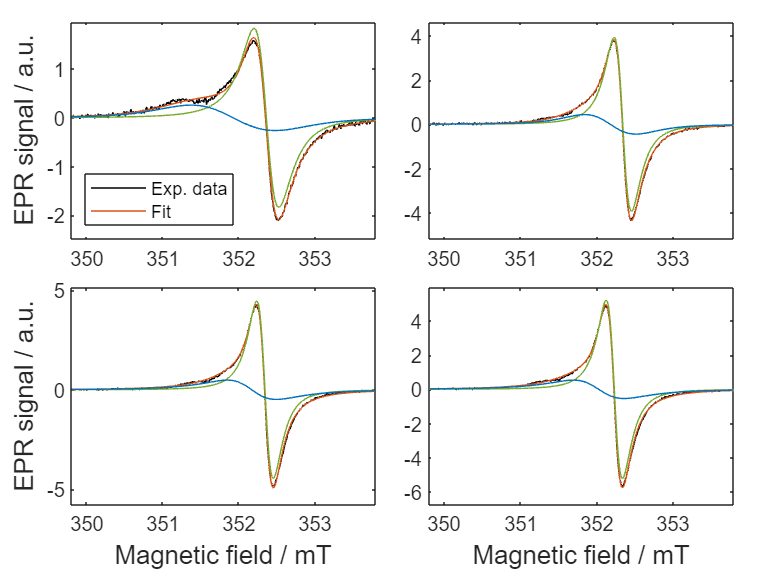

clearvars
load("plotColors.mat")
iData = 1;
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
iSample = 0;
for jj = 34:37
    pathLoad = strcat("data/processed/gm-e1-000", string(jj), ".mat");
    dataArray(iData) = load(pathLoad);

    xx = dataArray(iData).data.x;
    yy = dataArray(iData).data.y;
    fitfit = dataArray(iData).data.Fit.fit;
    yFit = dataArray(iData).data.Fit.yFit;

    nexttile
    plot(xx, yy, 'Color', plotColors(1), 'DisplayName', 'Exp. data')
    hold on
    plot(xx, fitfit, 'Color', plotColors(2), 'DisplayName', 'Fit')
    for isys = 1:numel(yFit(:, 1))
        plot(xx, yFit(isys, :), 'Color', plotColors(isys + 2), 'HandleVisibility', 'off')
        yFitDI1 = cumtrapz(cumtrapz(yFit(1, :)));
        yFitDI2 = cumtrapz(cumtrapz(yFit(2, :)));
    end
    iSample = iSample + 1;
    nSpin1(iSample) = yFitDI1(end);
    nSpin2(iSample) = yFitDI2(end);

    xlim(setaxlim(xx, -0.3))
    ylim(setaxlim(yy, 0.1))
    
    if jj == 34; legend('Location', 'southwest'); end
    iData = iData + 1;
end
labelAxesFig(tL, "Magnetic field / mT", "EPR signal / a.u.")

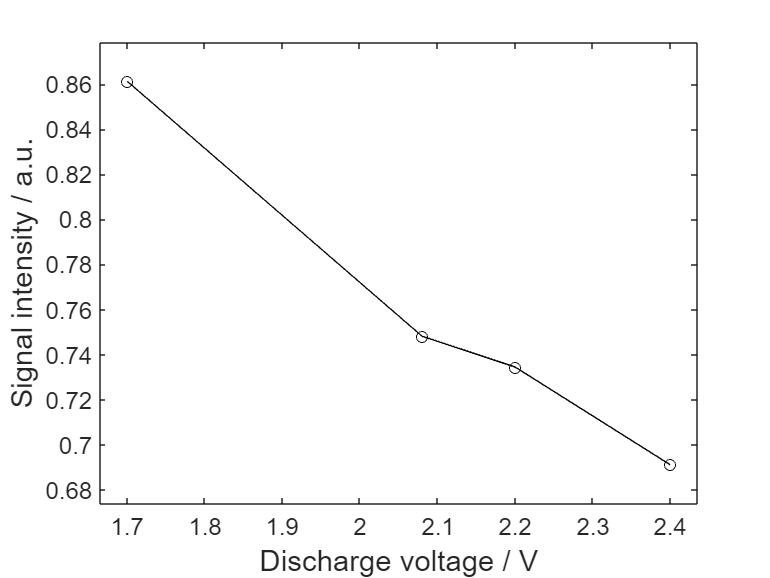

% savefigas(gcf, 'reports/figures/sijia-fig-00005.svg')

% X-band
disV = [2.4, 2.2, 2.08, 1.7];
powerFactor = [1, 1, 1, 1]; % all spectra 24 dB
weightFactor = [1, 1, 1, 1]; % all weights more or less the same
nSpin1_ = nSpin1; %(2:4);
disV_ = disV; %(2:4);
nSpin2_ = nSpin2; %(2:4)
powerFactor_ = powerFactor; %(2:4);
weightFactor_ = weightFactor; %(2:4);
xx = disV_;
yy = nSpin1_./weightFactor_./powerFactor_/10000;
yy2 = nSpin2_./weightFactor_./powerFactor_/10000;
figure()
plot(xx, yy, 'o-', 'Color', plotColors(1))
xlim(setaxlim(xx, 0.05))
ylim(setaxlim(yy, 0.1))
labelAxesFig(gca, "Discharge voltage / V", "Signal intensity / a.u.")
% savefigas(gcf, 'reports/figures/sijia-fig-00009.svg')

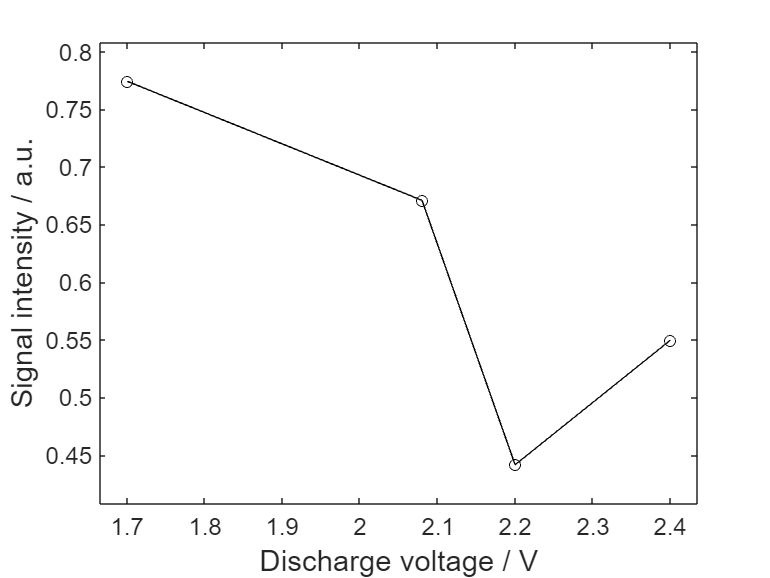

figure()
plot(xx, yy2, 'o-', 'Color', plotColors(1))
xlim(setaxlim(xx, 0.05))
ylim(setaxlim(yy2, 0.1))
labelAxesFig(gca, "Discharge voltage / V", "Signal intensity / a.u.")
% savefigas(gcf, 'reports/figures/sijia-fig-00010.svg')

for iData = 1:numel(dataArray)
    Sys = dataArray(iData).data.Fit.SysBest;
    for isys = 1:numel(Sys)
        fprintf('data %d sys %d weightDI %f\n', iData, isys, Sys{isys}.weightDI)
    end
end

# cw Q-band

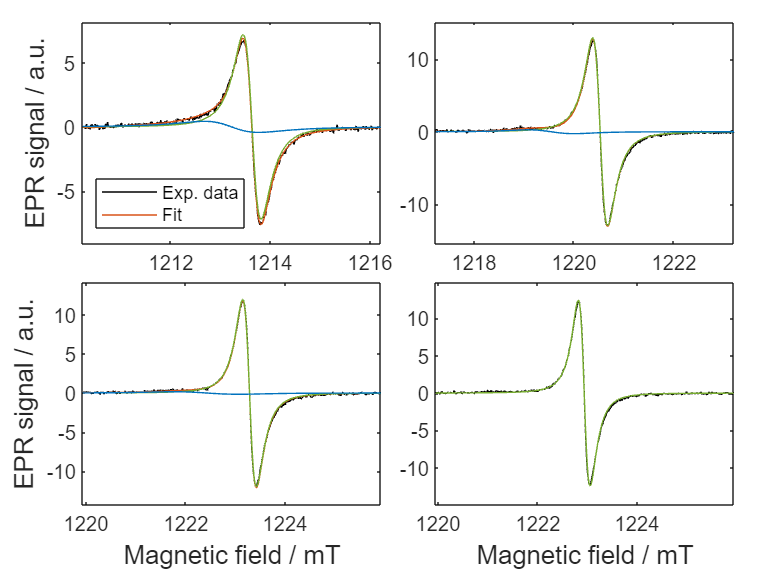

clearvars
load("plotColors.mat")
iData = 1;
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
iSample = 0;
for jj = [41, 43, 45, 47]
    pathLoad = strcat("data/processed/gm-e1-000", string(jj), ".mat");
    dataArray(iData) = load(pathLoad);

    xx = dataArray(iData).data.x;
    yy = dataArray(iData).data.y;
    fitfit = dataArray(iData).data.Fit.fit;
    yFit = dataArray(iData).data.Fit.yFit;

    nexttile
    plot(xx, yy, 'Color', plotColors(1), 'DisplayName', 'Exp. data')
    hold on
    plot(xx, fitfit, 'Color', plotColors(2), 'DisplayName', 'Fit')
    for isys = 1:numel(yFit(:, 1))
        if isys == 3
            continue
        end
        plot(xx, yFit(isys, :), 'Color', plotColors(isys + 2), 'HandleVisibility', 'off')
        yFitDI1 = cumtrapz(cumtrapz(yFit(1, :)));
    end
    iSample = iSample + 1;
    nSpin(iSample) = yFitDI1(end);

    xlim(setaxlim(xx, -0.3) - 1)
    ylim(setaxlim(yy, 0.1))
    
    if jj == 41; legend('Location', 'southwest'); end
    iData = iData + 1;
end
labelAxesFig(tL, "Magnetic field / mT", "EPR signal / a.u.")

% exportFig(gcf, 'reports/figures', 'sijia-fig-00006', '.svg')

disV = [0, 2.2, 2.08, 1.7];
powerFactor = [2, 1, 1, 1]; % first one at 18dB, others at  24dB
weightFactor = [2, 3, 2, 1]; % the second number is invented!!
nSpin_ = nSpin(2:4);
disV_ = disV(2:4);
powerFactor_ = powerFactor(2:4);
weightFactor_ = weightFactor(2:4);
xx = disV_;
yy = nSpin_./weightFactor_./powerFactor_/10000;
figure('Visible','off')
plot(xx, yy, 'o-', 'Color', plotColors(1))
xlim(setaxlim(xx, 0.05))
ylim(setaxlim(yy, 0.1))

labelAxesFig(gca, "Discharge voltage / V", "Double integral / a.u.")


clearvars
load("plotColors.mat")
iData = 1;

iSample = 0;
for jj = [41, 42, 44, 46]
    pathLoad = strcat("data/processed/gm-e1-000", string(jj), ".mat");
    dataArray(iData) = load(pathLoad);

    xx = dataArray(iData).data.x;
    yy = dataArray(iData).data.y;
    fitfit = dataArray(iData).data.Fit.fit;
    yFit = dataArray(iData).data.Fit.yFit;
    for isys = 1:numel(yFit(:, 1))
        if isys == 3
            continue
        end
        if jj == 41
            yFitDI1 = cumtrapz(cumtrapz(yFit(1, :)));
        else
            yFitDI1 = cumtrapz(cumtrapz(fitfit));
        end
    end
    iSample = iSample + 1;
    nSpin(iSample) = yFitDI1(end);
    
    iData = iData + 1;
end
disV = [0, 2.2, 2.08, 1.7];
powerFactor = [4, 1, 1, 1]; % first one at 18dB, others at  30dB
weightFactor = [2, 3, 2, 1];
nSpin_ = nSpin(2:4);
disV_ = disV(2:4);
powerFactor_ = powerFactor(2:4);
weightFactor_ = weightFactor(2:4);
xx = disV_;
yy = nSpin_./weightFactor_./powerFactor_/10000;
figure('Visible', 'off')
plot(xx, yy, 'o-', 'Color', plotColors(2))
xlim(setaxlim(xx, 0.05))
ylim(setaxlim(yy, 0.1))
labelAxesFig(gca, "Discharge voltage / V", "Double integral / a.u.")

# Q-band SCOF006

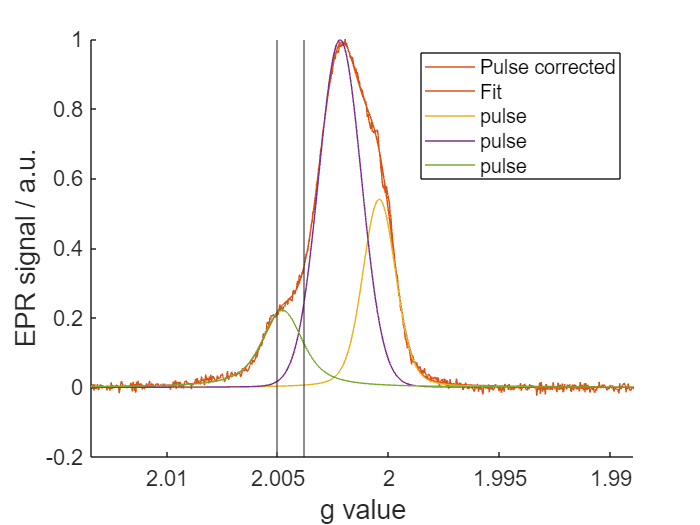

clearvars
load("plotColors.mat");

figure()
iData = 1;
for isys = [44, 50]
    pathLoad = strcat("data/processed/gm-e1-000", string(isys), ".mat");
    dataArray(iData) = load(pathLoad);

    gax(iData, :) = planck.*dataArray(iData).data.Params.MWFQ./bmagn./(dataArray(iData).data.x./1000);
    
    yy(iData, :) = dataArray(iData).data.y/max(dataArray(iData).data.y);
    if iData == 1
        for ii = 1:2
            y_{iData}.y(ii, :) = cumtrapz(dataArray(iData).data.Fit.yFit(ii, :));
            y_{iData}.y(ii, :) = y_{iData}.y(ii, :);
        end   
    elseif iData == 2
        gtemp = planck.*dataArray(iData).data.Params.MWFQ./bmagn./((dataArray(iData).data.DataPrep.xRaw + 2.9)./10000);

        for ii = 1:3
            y_{iData}.fitfit = dataArray(iData).data.Fit.fit/max(dataArray(iData).data.y);
            y_{iData}.y(ii, :) = dataArray(iData).data.Fit.yFit(ii, :);
            y_{iData}.y(ii, :) = y_{iData}.y(ii, :);
        end   
    end

    if iData > 1
        plot(gax(iData, :) - 0.003, yy(iData, :), "DisplayName", "Pulse corrected", "Color", plotColors(2))
        hold on
        plot(gax(iData, :) - 0.003, y_{iData}.fitfit, "DisplayName", "Fit", "Color", plotColors(2))
        % plot(gtemp, yy(iData, :), "DisplayName", "Pulse raw", "Color", plotColors(3))
        for ii = 1:3
            plot(gax(iData, :) - 0.003, y_{iData}.y(ii, :)/12e5, "DisplayName", "pulse")
        end
    end

    hold on
    iData = iData + 1;
end
set(gca, 'Xdir', 'reverse')
xlim(setaxlim(gax(1, :), 0))
% ylim(setaxlim(y_(1, :), 0.05))
legend();
labelAxesFig(gca, "g value", "EPR signal / a.u.")
pulseBandwidth = mhz2mt(1/48*1e3);
pulseBandwidthg = planck.*dataArray(end).data.Params.MWFQ./bmagn.*((1/1215.6*1000) - (1/(1215.6 - pulseBandwidth)*1000));
xline(planck.*dataArray(end).data.Params.MWFQ./bmagn./(1215.6/1000), "HandleVisibility", "off");
xline(planck.*dataArray(end).data.Params.MWFQ./bmagn./((1215.6 - pulseBandwidth)/1000), "HandleVisibility", "off");

% exportFig(gcf, 'reports/figures', 'sijia-fig-00007', '.svg')